% Initializing script
clc, clf, clear

constants;

% Design space for optimization
n_data = 10;    % number of data points
P_c = linspace(0.5*P_c_ref, 1.5*P_c_ref, n_data); % chamber pressure range (Pa)
A_t = linspace(0.5*A_t_ref, 1.5*A_t_ref, n_data); % throat area range (m2)
A_e = linspace(0.5*A_e_ref, 1.5*A_e_ref, n_data); % exit area range (m2)

## Convexity analysis

% Initializing objective function values
total_mass_P_c = zeros(1, length(P_c)); 
total_mass_A_t = zeros(1, length(A_t));
total_mass_A_e = zeros(1, length(A_e));

% Calculating objective function value w.r.t each design variables
for i = 1:length(P_c)
    total_mass_P_c(i) = calc_objective([P_c(i)/P_c_ref, 1, 1]);
    total_mass_A_t(i) = calc_objective([1, A_t(i)/A_t_ref, 1]);
    total_mass_A_e(i) = calc_objective([1, 1, A_e(i)/A_e_ref]);
end

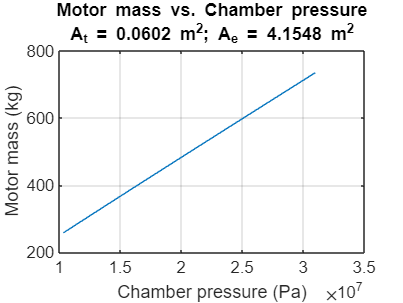

% Plotting results
plot(P_c, total_mass_P_c)
xlabel('Chamber pressure (Pa)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Chamber pressure' 'A_t = 0.0602 m^2; A_e = 4.1548 m^2'})
grid on

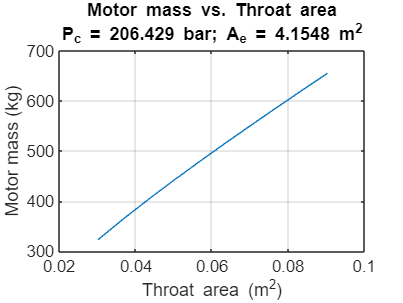


plot(A_t, total_mass_A_t)
xlabel('Throat area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Throat area' 'P_c = 206.429 bar; A_e = 4.1548 m^2'})
grid on

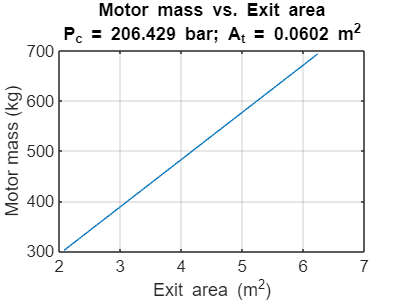


plot(A_e, total_mass_A_e)
xlabel('Exit area (m^2)')
ylabel('Motor mass (kg)')
title({'Motor mass vs. Exit area' 'P_c = 206.429 bar; A_t = 0.0602 m^2'})
grid on

## Calculating objective function in design space

% Initializing objective and constraint function values
total_mass_val = zeros(length(P_c), length(A_t), length(A_e));
ineq_constraint = zeros(length(P_c), length(A_t), length(A_e));
eq_constraint = zeros(length(P_c), length(A_t), length(A_e));

% Calculating objective and constraint functions
for i = 1:length(P_c)
    for j = 1:length(A_t)
        for k = 1:length(A_e)
            x_scaled = scale([P_c(i), A_t(j), A_e(k)], x_ref);
            total_mass_val(i, j, k) = calc_objective(x_scaled);
            [ineq_constraint(i,j,k), eq_constraint(i,j,k)] = calc_constraints(x_scaled);
        end
    end
end

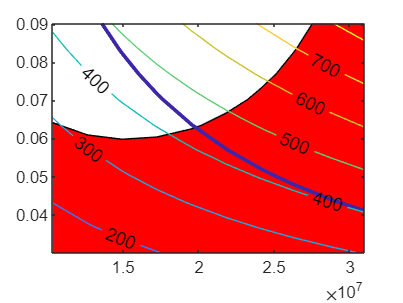

% Example plot
clf
i = 4;
contourf(P_c, A_t, ineq_constraint(:, :, i), [0,0], 'FaceColor', '#FF0000');
hold on
[M,c] = contour(P_c, A_t, eq_constraint(:, :, i), [0,0]);
c.LineWidth = 2;
contour(P_c, A_t, total_mass_val(:,:, i), 'ShowText','on')
hold off

%% Sample SQP conditions
% Linear constraints
A = []; 
b = [];
Aeq = [];
beq = [];

% Design variable bounds
lb = [0.1, 0.1, 0.1];
ub = [10, 10, 10];

options = optimoptions('fmincon','Display','iter','Algorithm','sqp');
x0 = [1, 1, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    3.116809e+04     7.379e-02     1.000e+00     0.000e+00     2.655e+04  
    1           8    7.344014e+03     4.570e+00     1.000e+00     1.553e+00     3.175e+04  
    2          15    7.964866e+03     3.494e+00     3.430e-01     2.767e+00     2.004e+04  
    3          19    7.647320e+03     1.897e+00     1.000e+00     2.293e+00     1.358e+04  
    4          24    9.005686e+03     1.036e+00     7.000e-01     2.139e+00     1.075e+04  
    5          28    1.090854e+04     3.607e-01     1.000e+00     1.015e+00     1.663e+04  
    6          32    1.105024e+04     1.083e-01     1.000e+00     3.984e+00     1.356e+03  
    7          36    1.218394e+04     4.101e-02     1.000e+00     6.779e-01     1.948e+03  
    8          40    1.241747e+04     1.418e-03     1.000e+00     6.490e-02     6.

x =     0.2516    3.8655    7.8079


fval = 1.2429e+04

exitflag = 1

output = struct with fields:
         iterations: 11
          funcCount: 52
          algorithm: 'sqp'
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 3.962933e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 1.872102e-10, is less than options.ConstraintTolerance = 1.000000e-06.'
    constrviolation: 1.8721e-10
           stepsize: 4.5041e-04
       lssteplength: 1
      firstorderopt: 0.0119
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: -1.9305e+03
       ineqlin: [0×1 double]
    ineqnonlin: 7.4364e+04
         lower: [3×1 double]
         upper: [3×1 double]


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1459198.322385
Throat area = 0.729036
Exit area = 6.010553
Total Mass = 12428.637509

options = optimoptions('fmincon','Display','iter','Algorithm','active-set');
x0 = [0.7, 0.75, 1];
[x, fval, exitflag, output, lambda] = fmincon(@calc_objective_test, x0, ...
    A, b, Aeq, beq, lb, ub, @calc_constraints, options)


                                Max     Line search  Directional  First-order 
 Iter F-count        f(x)   constraint   steplength   derivative   optimality Procedure 
    0      4      2784.86       0.4643                                         Infeasible start point
    1      9      2037.84       0.4351          0.5         -615          809   
    2     14       1833.3       0.3869          0.5        -66.3     1.28e+03  Hessian modified  
    3     18      2454.32      0.04263            1          954         51.9   
    4     22      2433.04     0.003425            1        -57.3          111   
    5     32      2429.98       0.0035       0.0156        -46.8         56.9   
    6     37      2419.31     0.004374          0.5        -28.5          103   
    7     41      2418.31     0.002964            1         2.77         2.94   
    8     45      2423.99    2.387e-05            1         94.2         2.37   
    9     49      2424.06    3.992e-07            1         13.9

x =     0.3223    3.1027    4.1615


fval = 2.4241e+03

exitflag = 5

output = struct with fields:
         iterations: 12
          funcCount: 57
       lssteplength: 1
           stepsize: 5.3965e-06
          algorithm: 'active-set'
      firstorderopt: 3.0228e-04
    constrviolation: 3.4539e-11
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the predicted change in the objective function↵is less than the value of the function tolerance and constraints ↵are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the predicted change in the objective function,↵8.438226e-08, is less than options.FunctionTolerance = 1.000000e-06, and the maximum constraint↵violation, 3.453937e-11, is less than options.ConstraintTolerance = 1.000000e-06.'
       bestfeasible: [1×1 struct]


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: 1.4138e+03
       ineqlin: [0×1 double]
    ineqnonlin: 4.3422e+03


x = descale(x, x_ref);
fprintf('Chamber pressure = %f\nThroat area = %f\nExit area = %f\nTotal Mass = %f' ...
    , x(1), x(2), x(3), fval)

Chamber pressure = 1869326.973832
Throat area = 0.585173
Exit area = 3.203526
Total Mass = 2424.058377

calc_objective_test(scale(x, x_ref))

V_UDMH = 78.4286

V_N2O4 = 73.1133

L_UDMH_tank = 5.0736

L_N2O4_tank = 4.5581

t_cyl = 0.0255

t_sph = 0.0127

mass_UDMH_tank = 5.8267e+03

mass_N2O4_tank = 5.2977e+03

chamber_mass = 154.2124

injector_mass = 723.3444

nozzle_divergent_mass = 481.0611

ans = 1.2483e+04

calc_objective_test(scale(x, x_ref))

V_UDMH = 16.2008

V_N2O4 = 15.1028

L_UDMH_tank = -1.9876e-05

L_N2O4_tank = -2.2076e-05

t_cyl = 0.0297

t_sph = 0.0149

mass_UDMH_tank = 723.9071

mass_N2O4_tank = 723.9045

ans = 2.4241e+03